# Ejercicio 2.3: Masa-muelle-amortiguador

**a)**

Partimos de la ecuación del sistema

$\ddot y = \frac{1}{m} \left(F (t) - c \dot y - k y\right)$.

Tomando la velocidad y la posición como variables de estado, se deducen las ecuaciones del modelo 

$x=\left\lbrack \begin{array}{c}
y\\
\dot{y} 
\end{array}\right\rbrack \Rightarrow \frac{\mathrm{d}}{\textrm{dt}}\left\lbrack \begin{array}{c}
y\\
\dot{y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{\;y} \\
\ddot{\;y} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{\;y} \\
\frac{1}{m}\left(F\left(t\right)-c\dot{y} -\textrm{ky}\right)
\end{array}\right\rbrack$.

La fuerza externa F se considera la entrada del sistema.

**b) y c)**

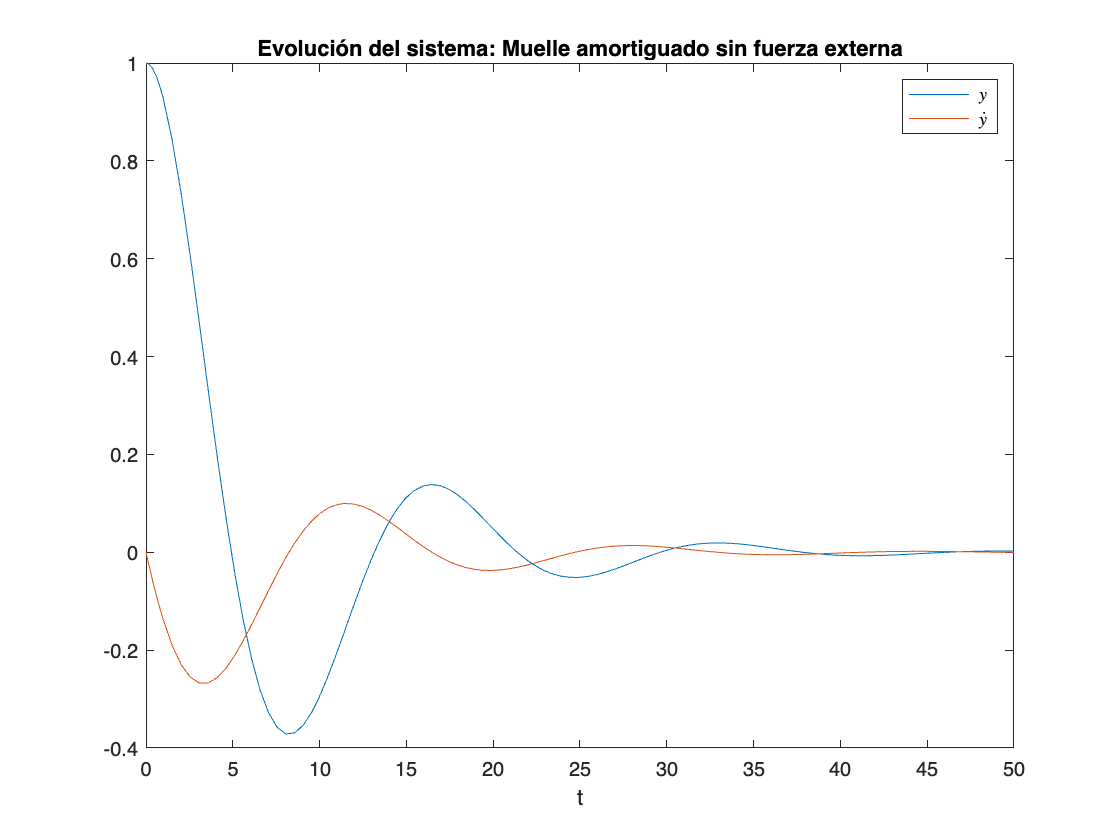

m = 2.5; %kg
c = 0.6; %N * s / m
k = 0.4; %N / m
F = 0;

x0 = [1; 0];
tspan = [0, 50]; %s

[t, x] = ode45(@(t, x)muelle(t, x, m, c, k, F), tspan, x0);

figure(1)
plot(t, x)
legend("$y$", "$\dot y$", "interpreter", "LaTeX")
title("Evolución del sistema: Muelle amortiguado sin fuerza externa")
xlabel("t")

**d)**

Ahora tenemos una fuerza constante de 1 N.

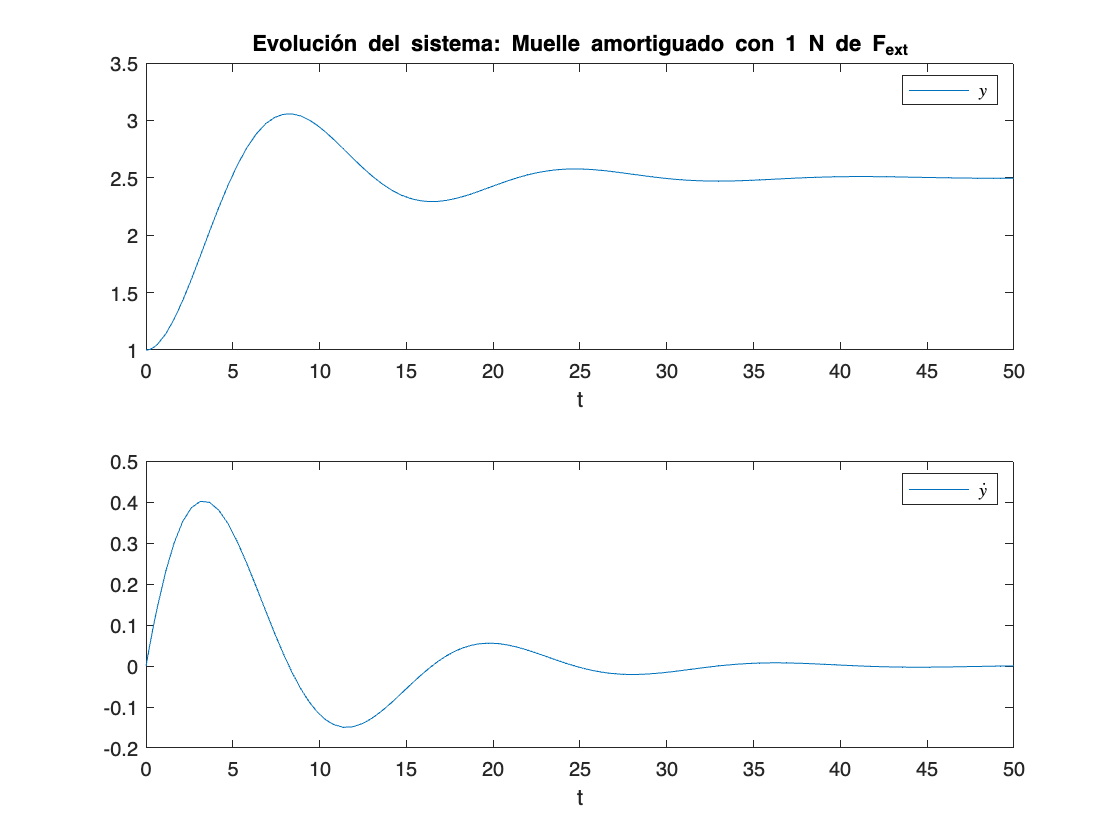

F = 1;

[t, x] = ode45(@(t, x)muelle(t, x, m, c, k, F), tspan, x0);

figure(2)
subplot(2, 1, 1);
plot(t, x(:, 1))
legend("$y$", "interpreter", "LaTeX")
title("Evolución del sistema: Muelle amortiguado con 1 N de F_{ext}")
xlabel("t")

subplot(2, 1, 2);
plot(t, x(:, 2))
xlabel("t")
legend("$\dot{y}$", "interpreter", "LaTeX")


%Se aprecia que el muelle se para en otra posición de equilibrio porque la
%fuerza es constante en la misma dirección. 

**e)**

Ahora la entrada es un sinusoide con frecuencia angular 0.1 rad/s

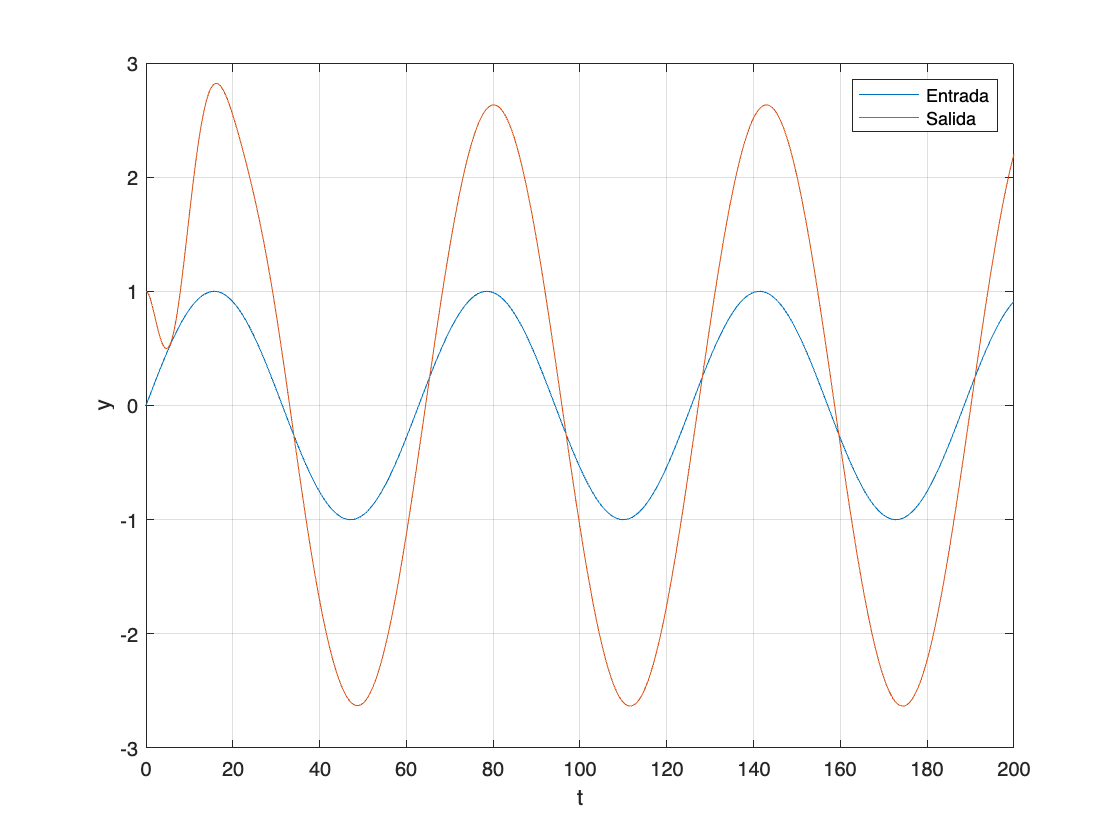

tspan = [0, 200];
w = 0.1;
Fs = @(F, w, t) (F * sin(w * t));

[t, x] = ode45(@(t, x)muelle(t, x, m, c, k, Fs(F, w, t)), tspan, x0);

figure(3)
plot(t, Fs(F, w, t)); hold on, grid on;
plot(t, x(:, 1)); 
legend("Entrada", "Salida")
xlabel("t")
ylabel("y")
hold off;


%A partir del segundo 50 la señal de salida se estabiliza y replica  
%la entrada con un ligero desfase.

**f)**

Repetimos lo anterior cambiando la frecuencia de la señal.

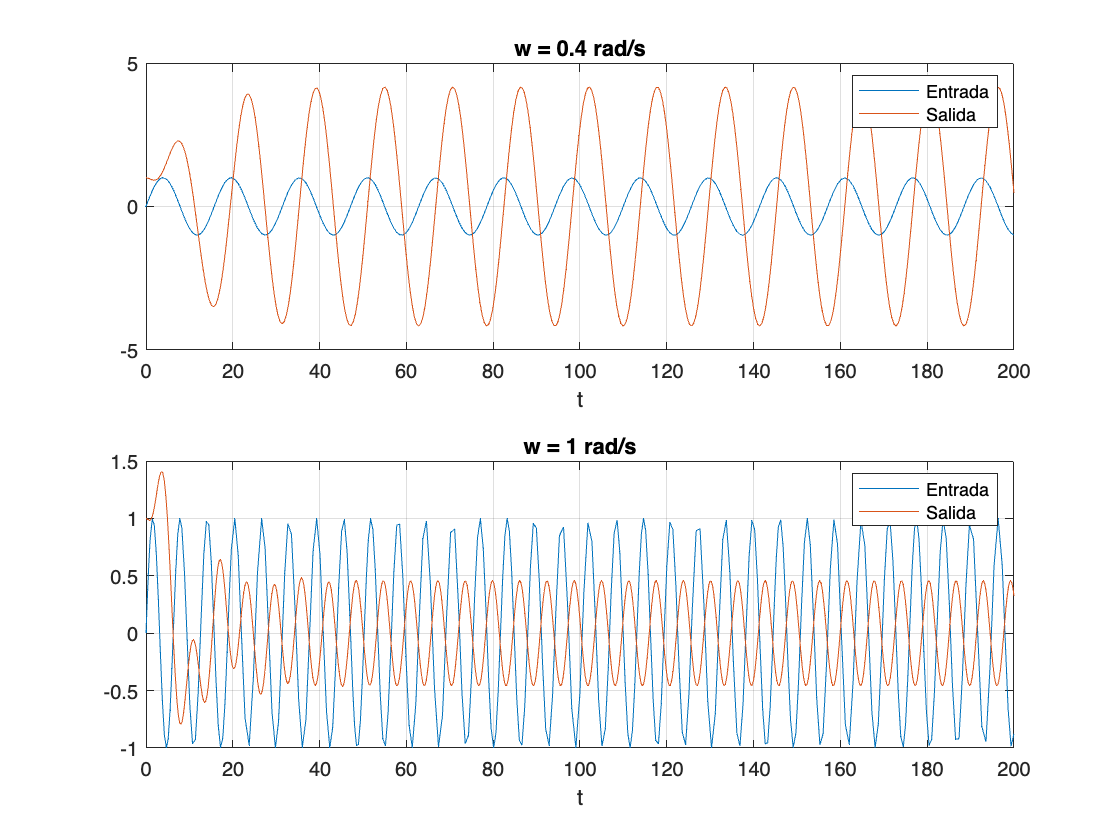

[t1, x1] = ode45(@(t, x)muelle(t, x, m, c, k, Fs(F, 0.4, t)), tspan, x0);
[t2, x2] = ode45(@(t, x)muelle(t, x, m, c, k, Fs(F, 1, t)), tspan, x0);

figure(4)

subplot(2, 1, 1)
plot(t, Fs(F, 0.4, t)); hold on, grid on;
plot(t1, x1(:, 1)); 
title("w = 0.4 rad/s")
xlabel("t")
legend("Entrada", "Salida")
hold off;

subplot(2, 1, 2)
plot(t, Fs(F, 1, t)); hold on, grid on;
plot(t2, x2(:, 1)); 
title("w = 1 rad/s")
xlabel("t")
legend("Entrada", "Salida")
hold off;


%Parece que a mayor frecuencia la señal se estabiliza antes. 

function xdot = muelle(t, x, m, c, k, F)
    xdot(1, 1) = x(2, 1);
    xdot(2, 1) = 1/m * (F - c * x(2, 1) - k * x(1, 1));
end